load 'consumi.txt'
disp(consumi)

   10.0000   10.2000
   20.2000    9.5000
   29.5000    9.0000
   40.5000    8.5000
   50.1000    8.0000
   59.9000    7.3000
   70.4000    6.8000
   80.2000    6.4000
   90.5000    6.3000
  110.5000    6.2000
  129.4000    7.1000
  149.1000    8.3000



x = consumi(:,1)

x =    10.0000
   20.2000
   29.5000
   40.5000
   50.1000
   59.9000
   70.4000
   80.2000
   90.5000
  110.5000


y = consumi(:,2)

y =    10.2000
    9.5000
    9.0000
    8.5000
    8.0000
    7.3000
    6.8000
    6.4000
    6.3000
    6.2000


plot(x,y,"Marker",".")
hold on
title('Average speed per liter')
xlabel('kmph')
ylabel('liters')

p =polyfit(x,y,3)

p =     0.0000   -0.0003   -0.0521   10.7311


f = polyval(p,x)

f =    10.1844
    9.5891
    9.0323
    8.3811
    7.8404
    7.3359
    6.8714
    6.5303
    6.2908
    6.2614


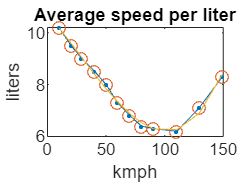

plot(x,y,'o',x,f,'-')


z = (consumi(9,2) + consumi(10,2))/2

z = 6.2500

R = corrcoef(x,f)

R =     1.0000   -0.6428
   -0.6428    1.0000
